ESCALÓN FR

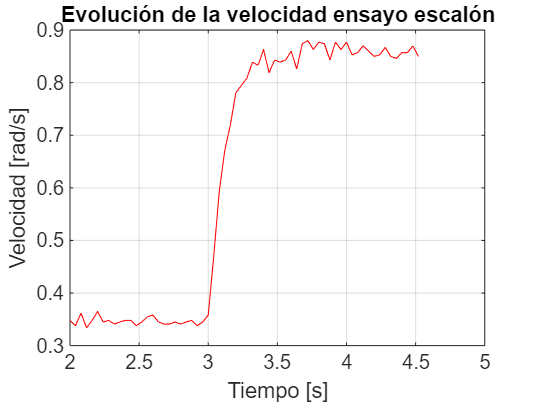

escalon=[
2.000 47 10.710 0.348
2.040 47 10.395 0.338
2.080 47 11.130 0.362
2.120 47 10.290 0.334
2.160 47 10.710 0.348
2.200 47 11.235 0.365
2.240 47 10.605 0.345
2.280 47 10.710 0.348
2.320 47 10.500 0.341
2.360 47 10.605 0.345
2.400 47 10.710 0.348
2.440 47 10.710 0.348
2.480 47 10.395 0.338
2.520 47 10.605 0.345
2.560 47 10.920 0.355
2.600 47 11.025 0.358
2.640 47 10.605 0.345
2.680 47 10.500 0.341
2.720 47 10.500 0.341
2.760 47 10.605 0.345
2.800 47 10.500 0.341
2.840 47 10.605 0.345
2.880 47 10.710 0.348
2.920 47 10.395 0.338
2.960 47 10.605 0.345
3.000 150 11.025 0.358
3.040 150 14.490 0.471
3.080 150 18.269 0.594
3.120 150 20.685 0.672
3.160 150 22.155 0.720
3.200 150 24.044 0.781
3.240 150 24.464 0.795
3.280 150 24.885 0.809
3.320 150 25.830 0.839
3.360 150 25.619 0.833
3.400 150 26.564 0.863
3.440 150 25.200 0.819
3.480 150 25.935 0.843
3.520 150 25.829 0.839
3.560 150 25.935 0.843
3.600 150 26.459 0.860
3.640 150 25.410 0.826
3.680 150 26.879 0.874
3.720 150 27.090 0.880
3.760 150 26.565 0.863
3.800 150 26.985 0.877
3.840 150 26.880 0.874
3.880 150 25.935 0.843
3.920 150 26.984 0.877
3.960 150 26.565 0.863
4.000 150 26.985 0.877
4.040 150 26.249 0.853
4.080 150 26.355 0.857
4.120 150 26.774 0.870
4.160 150 26.460 0.860
4.200 150 26.144 0.850
4.240 150 26.250 0.853
4.280 150 26.670 0.867
4.320 150 26.145 0.850
4.360 150 26.040 0.846
4.400 150 26.354 0.857
4.440 150 26.354 0.857
4.480 150 26.774 0.870
4.520 150 26.145 0.850
];

t = escalon(:,1);
refPWM = escalon(:,2);
u = refPWM - refPWM(1); %Entrada del System Identification
w    = escalon(:,3);
vel = escalon(:,4);
y = vel - vel(1); %Salida del System Identification

figure
plot(t, vel, 'r');
xlabel('Tiempo [s]');
ylabel('Velocidad [rad/s]');
title('Evolución de la velocidad ensayo escalón');
grid on;

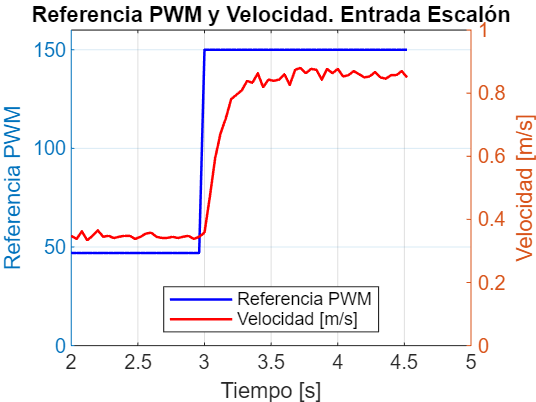


figure;
% Eje izquierdo (referencia PWM)
yyaxis left
p1 = plot(t, refPWM, 'b-', 'LineWidth', 1.2); hold on;
ylim([0 160]);                 % límites del eje izquierdo
ylabel('Referencia PWM');

% Eje derecho (velocidad)
yyaxis right
p2 = plot(t, vel, 'r-', 'LineWidth', 1.2); hold on;
ylim([0 1]);                    % límites del eje derecho
ylabel('Velocidad [m/s]');

xlabel('Tiempo [s]');
title('Referencia PWM y Velocidad. Entrada Escalón');
grid on;

legend({'Referencia PWM','Velocidad [m/s]'}, 'Location','south');

RESPUESTA AL ESCALÓN EN BUCLE ABIERTO

figure
G=tf(tf1) %cargamos nuestro modelo de System Identification


G =
 
  From input "u1" to output "y1":
     0.001069
  ---------------
  1 - 0.7872 z^-1
 
Name: tf1
Sample time: 0.04 seconds
Discrete-time transfer function.
Model Properties


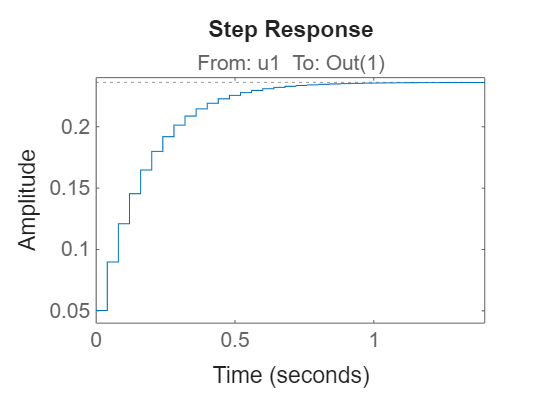

step(47*G) %Vemos la respuesta ante entrada escalón

OBTENCIÓN DE LOS CONTROLADORES PID

figure
%Ajuste manual PID
Kp = 500; Ki = 19000; Kd = 0.0; Ts=0.04;
Cd = pid(Kp, Ki, Kd, 'Ts', Ts)
T = feedback(Cd*G,1);
step(0.386*T)
xlim([0 2]);
grid on

%Hago el controlador con el PID Tuner
%Valores obtenidos con la APP PID Tuner
Kp_tuner = 129.4;
Ki_tuner = 1130;
Kd_tuner = 0;
Ts = 0.04;         

% Crear el controlador discreto
Cd_tuner = pid(Kp_tuner, Ki_tuner, Kd_tuner, 'Ts', Ts)


Cd_tuner =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 129, Ki = 1.13e+03, Ts = 0.04
 
Sample time: 0.04 seconds
Discrete-time PI controller in parallel form.
Model Properties


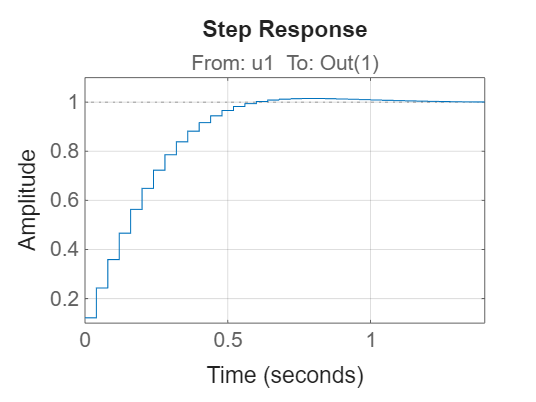

T_tuner=feedback(Cd_tuner*G,1);
step(1*T_tuner)
grid on

Resultados control PID Tuner

escalonPID_Tuner = [

];


t3 = escalonPID_Tuner(:,1);
refvel3 = escalonPID_Tuner(:,2);
refPWM3 = escalonPID_Tuner(:,3);
vel3    = escalonPID_Tuner(:,4);

figure
plot(t3, vel3, 'r');
xlabel('Tiempo [s]');
ylabel('Velocidad [rad/s]');
title('Evolución de la velocidad con ensayo escalón y PID hallado con PID Tuner');
grid on;

figure;
% Eje izquierdo (referencia velocidad rad/s)
yyaxis left
plot(t3, refvel3, 'b-', 'LineWidth', 1.2); hold on;
ylim([0 0.45]);                 % límites del eje izquierdo
ylabel('Referencia rad/s');

% Eje derecho (velocidad)
yyaxis right
plot(t3, vel3, 'r-', 'LineWidth', 1.2); hold on;
ylim([0 0.45]);                    % límites del eje derecho
ylabel('Velocidad [rad/s]');

xlabel('Tiempo [s]');
title('Referencia y Velocidad Angular Entrada Escalón');
grid on;

legend({'Referencia PWM','Velocidad [m/s]'}, 'Location','best');

Resultados control PID Manual

escalonPID_Manual=[
    ];

t4 = escalonPID_Manual(:,1);
refPWM4 = escalonPID_Manual(:,2);
vel4    = escalonPID_Manual(:,3);

figure
plot(t4, vel4, 'r');
xlabel('Tiempo [s]');
ylabel('Velocidad [rad/s]');
title('Ensayo escalón con PID con ajuste manual');
grid on;

figure;
% Eje izquierdo (referencia velocidad rad/s)
yyaxis left
plot(t4, refPWM4, 'b-', 'LineWidth', 1.2); hold on;
ylim([0 25]);                 % límites del eje izquierdo
ylabel('Referencia rad/s');

% Eje derecho (velocidad)
yyaxis right
plot(t4, vel4, 'r-', 'LineWidth', 1.2); hold on;
ylim([0 24]);                    % límites del eje derecho
ylabel('Velocidad [rad/s]');

xlabel('Tiempo [s]');
title('Referencia y Velocidad Angular Entrada Escalón');
grid on;

legend({'Referencia PWM','Velocidad [rad/s]'}, 'Location','best');


